Simulation of ACh sensor that should go to the paper.

% give this simulation a name
SimulationName='simulation_ACh_20221222';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20221222/'

cd(filepath)

datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/'

datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/'

stateYao_file = "/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM_fixedoffset_analysis_0607.mat"

stateYao_file = "/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM_fixedoffset_analysis_0607.mat"


all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

cd(datapath);
load(stateYao_file, 'stateYao');

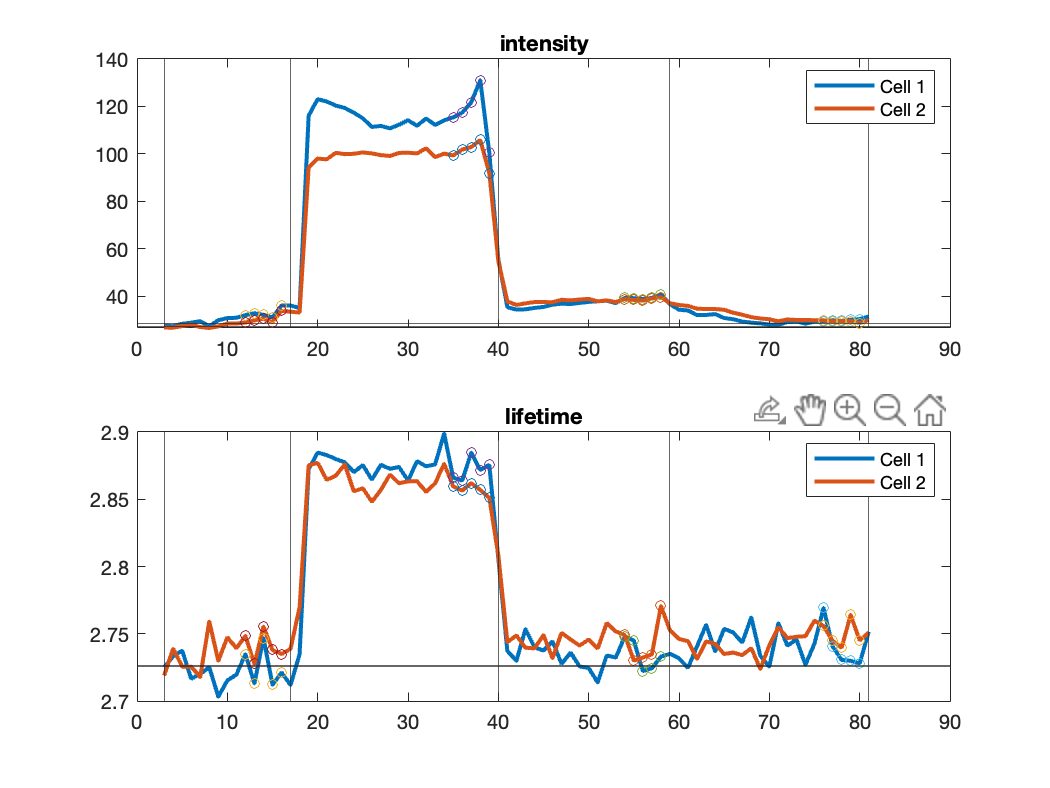

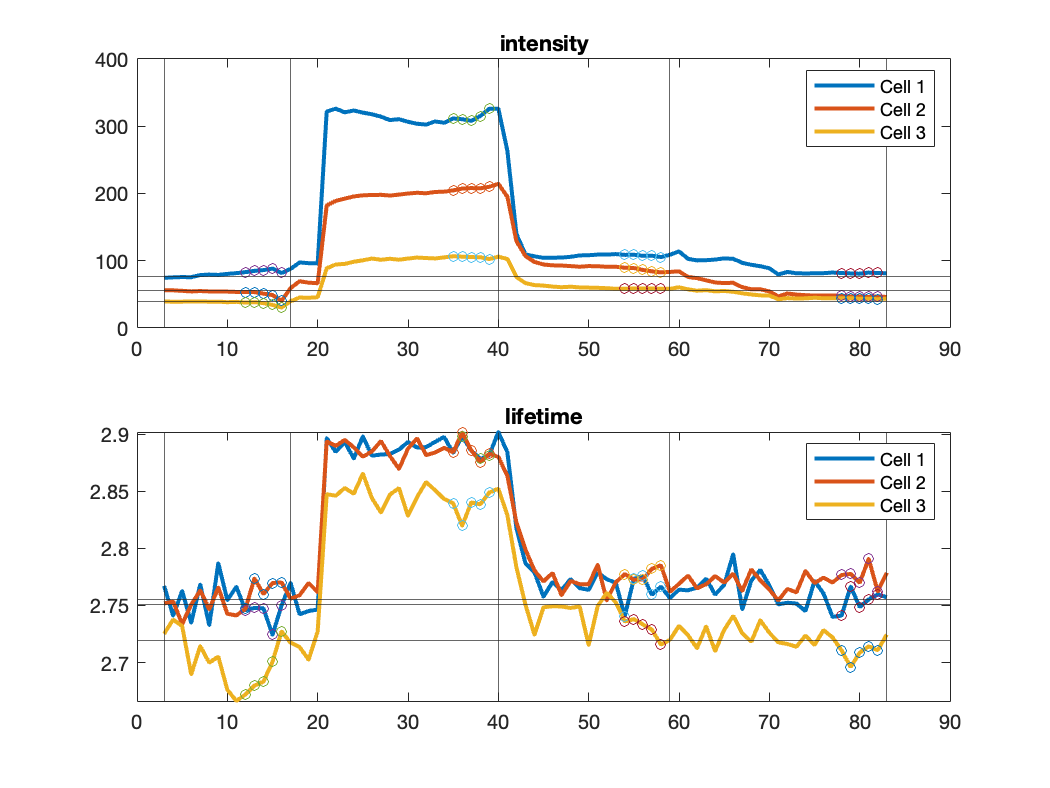

epoch_response_intensity_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_intensity_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_all = 1×2 cell array
    {4×2 double}    {4×3 double}


Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66,CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

baseline_index_cycle1 = 16;
ACh_index_cycle1 = 38;
baseline_index_cycle2 = 16;
ACh_index_cycle2 = 38;
baseline_acq_cycle1 = stateYao.CyclePositions(baseline_index_cycle1,1)

baseline_acq_cycle1 = 53

ACh_acq_cycle1 = stateYao.CyclePositions(ACh_index_cycle1,1)

ACh_acq_cycle1 = 119

baseline_acq_cycle2 = stateYao.CyclePositions(baseline_index_cycle2,2)

baseline_acq_cycle2 = 48

ACh_acq_cycle2 = stateYao.CyclePositions(ACh_index_cycle2,2)

ACh_acq_cycle2 = 114

% load the file of ACh sensor under ACh 100 uM condition
cd(datapath);
ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM119.mat'

spc_openCurves(ACh_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM119.mat


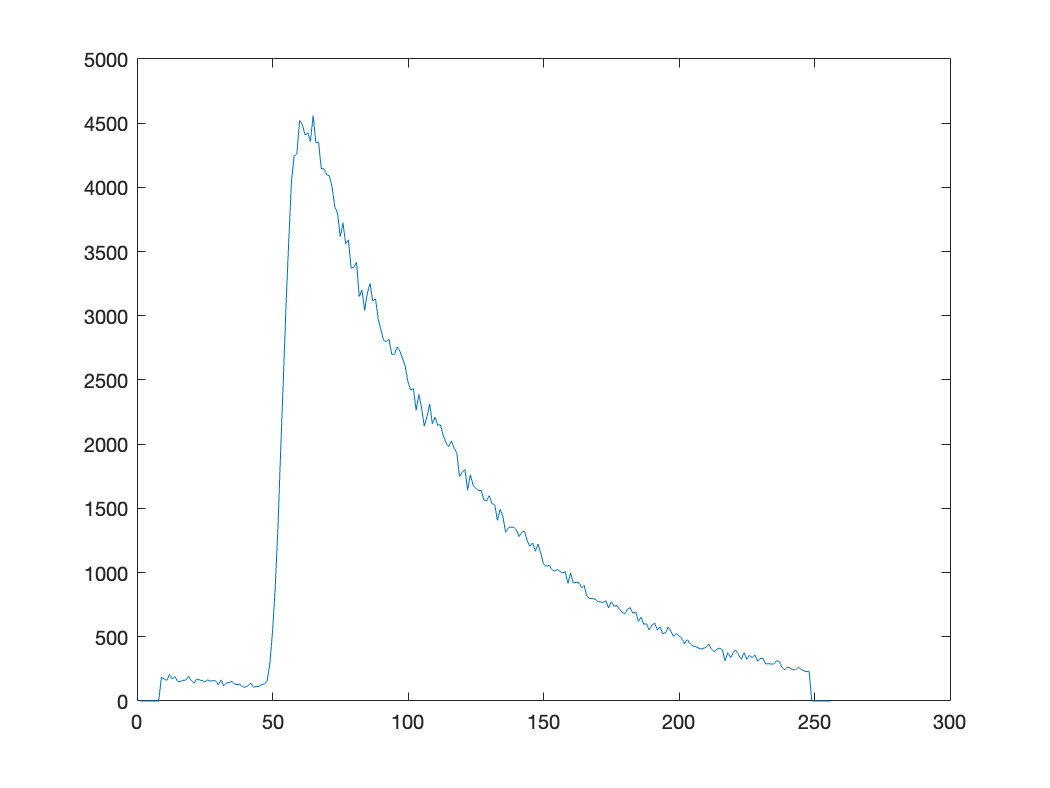

spc_lifetimes_cycle1 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{1}{ACh_index_cycle1},3)
    mask = stateYao.images.I_ROI_stack{1}{ACh_index_cycle1}(:,:,iCell);
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle1 = spc_lifetimes_cycle1 + spc.imageMods{1}(:,i_x, i_y);
            end
        end
    end
end

figure
plot(spc_lifetimes_cycle1)

ACh_spc_file_cycle2 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle2) '.mat']

ACh_spc_file_cycle2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM114.mat'

spc_openCurves(ACh_spc_file_cycle2)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM114.mat


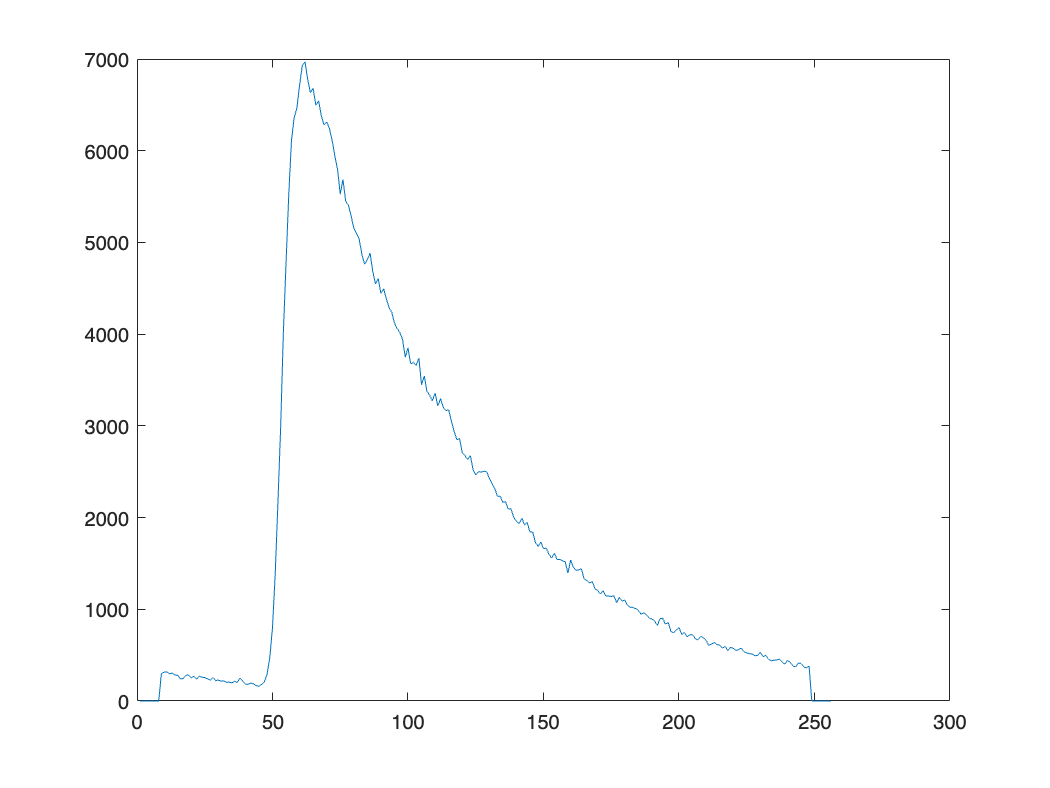

spc_lifetimes_cycle2 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{2}{ACh_index_cycle1},3)
    mask = stateYao.images.I_ROI_stack{2}{ACh_index_cycle2}(:,:,iCell);
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle2 = spc_lifetimes_cycle2 + spc.imageMods{1}(:,i_x, i_y);
            end
        end
    end
end

figure
plot(spc_lifetimes_cycle2)

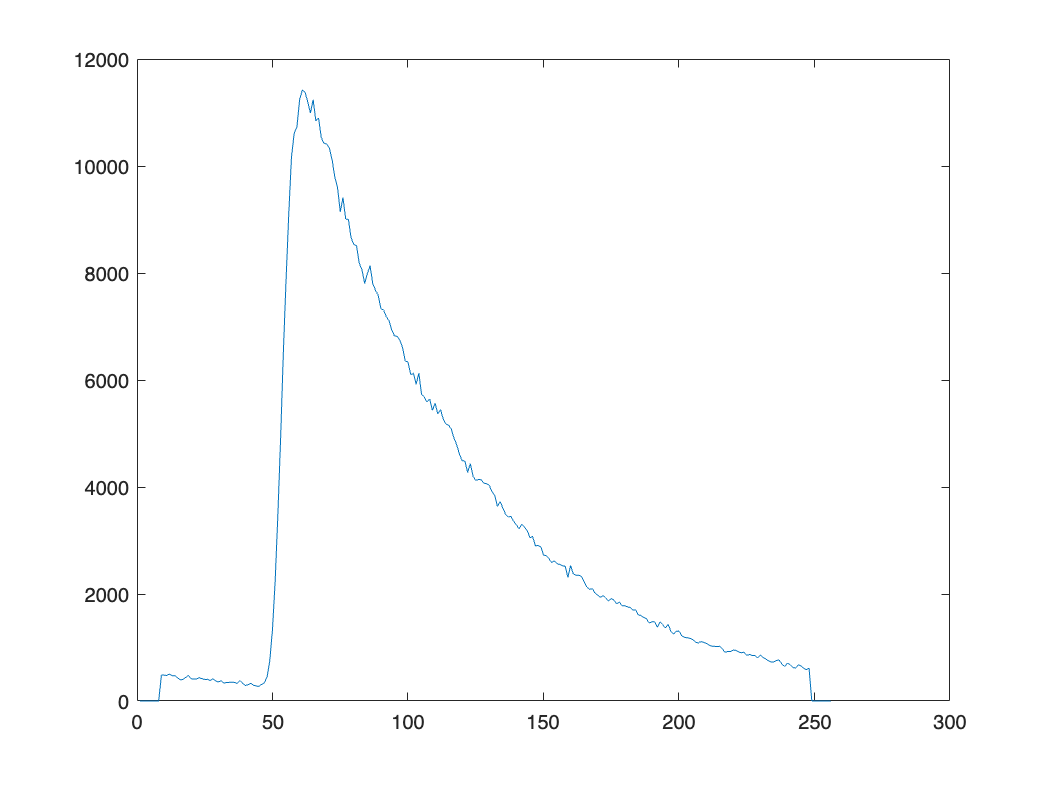

spc_lifetimes = spc_lifetimes_cycle1 + spc_lifetimes_cycle2;

figure
plot(spc_lifetimes)


spc.lifetimes{1} = spc_lifetimes'

spc = struct with fields:
         switchess: {[1×1 struct]  [1×1 struct]}
     GUI_switchess: [1×1 struct]
              fits: {[1×1 struct]}
          GUI_fits: [1×1 struct]
          filename: '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM114.mat'
              GUIS: [1×1 struct]
          datainfo: [1×1 struct]
               fit: [1×1 struct]
          switches: [1×1 struct]
         imageMods: {[256×128×128 double]}
      originalFile: 'C:\Users\User\Desktop\Pingchuan\0831HEKAchsensor003\0831HEKAchsensor003FLIM114.mat'
           SPCdata: [1×1 struct]
    imageModSlices: {}
       maxProjects: {[]}
         lifetimes: {[0 0 0 0 0 0 0 0 484 486 476 504 474 474 433 394 402 442 478 411 410 409 435 418 403 405 383 415 380 356 381 336 345 348 350 348 330 382 328 290 304 332 294 281 274 309 341 446 758 1340 2264 3510 4920 6511 7868 9105 10161 10611 … ]}
              size: [256 128 128]
          projects: {[128×1

% move the corresponding prf to this folder, load this prf and do the
% fitting
cd(filepath)
copyfile /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/prf.mat prf.mat

% after doing the fitting, output the fitting parameters

p1_ACh=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_ACh = 0.8986

p2_ACh=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_ACh = 0.1014

tau1_ACh=spc.fits{1,1}.beta2

tau1_ACh = 2.8618

tau2_ACh=spc.fits{1,1}.beta4

tau2_ACh = 0.2962

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0732

SHG=spc.fits{1,1}.beta6

SHG = 0

samplesize_ACh=sum(spc.lifetimes{1})

samplesize_ACh = 799744

SHG_proportion=SHG/samplesize_ACh

SHG_proportion = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 0.6374

backcorr=spc.fits{1,1}.backCorr

backcorr = 108.2686

chisq = spc.fits{1,1}.redchisq

chisq = 1.6462


% calculate the empirical lifetime from the histogram, considering the
% first 8 and last 8 channels are forced to be 0, and considering the
% fitting range.
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


weight_n_lft=lft_steps.*spc.lifetimes{1}(range(1):range(2))

weight_n_lft = 1.0e+04 *

    0.0024    0.0046    0.0074    0.0093    0.0116    0.0127    0.0135    0.0157    0.0194    0.0233    0.0221    0.0240    0.0260    0.0297    0.0306    0.0315    0.0336    0.0337    0.0385    0.0371    0.0365    0.0409    0.0377    0.0404    0.0425    0.0444    0.0459    0.0451    0.0541    0.0480    0.0439    0.0475    0.0535    0.0488    0.0480    0.0482    0.0558    0.0633    0.0849    0.1480    0.2683    0.4643    0.7370    1.0570    1.4306    1.7672    2.0895    2.3815    2.5388    2.6187


empirical_lft_ACh=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_ACh = 4.6654


% also export the histogram
n_exp_ACh=spc.lifetimes{1};
ACh_peak = find(n_exp_ACh == max(n_exp_ACh))

ACh_peak = 61

lft_steps=(1:1:256)*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


lft_steps(1:8)=0;
lft_steps(end-7:end)=0;
weight_n_lft=lft_steps(range(1):range(2)).*n_exp_ACh(range(1):range(2));
empirical_lft_ACh = sum(weight_n_lft)/sum(n_exp_ACh(range(1):range(2)))

empirical_lft_ACh = 5.1049


% calculate the empirical lifetime from the fitted curve


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*spc.fits{1,1}.curve';
empirical_lft_ACh_curve=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_ACh_curve = 4.6649

% save the fitting parameters
save('fitting_parameters.mat','p1_ACh','p2_ACh','tau1_ACh','tau2_ACh','delta_peak_time','SHG','samplesize_ACh','backcorr','empirical_lft_ACh','empirical_lft_ACh_curve')

% adjust the prf based on the delta peak time
% comment more the what the interpolation does and why doing that

load('prf.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_ACh=find(prf_interp1==max(prf_interp1))

prf_peak_ACh = 54

find(prf==max(prf))

ans = 53

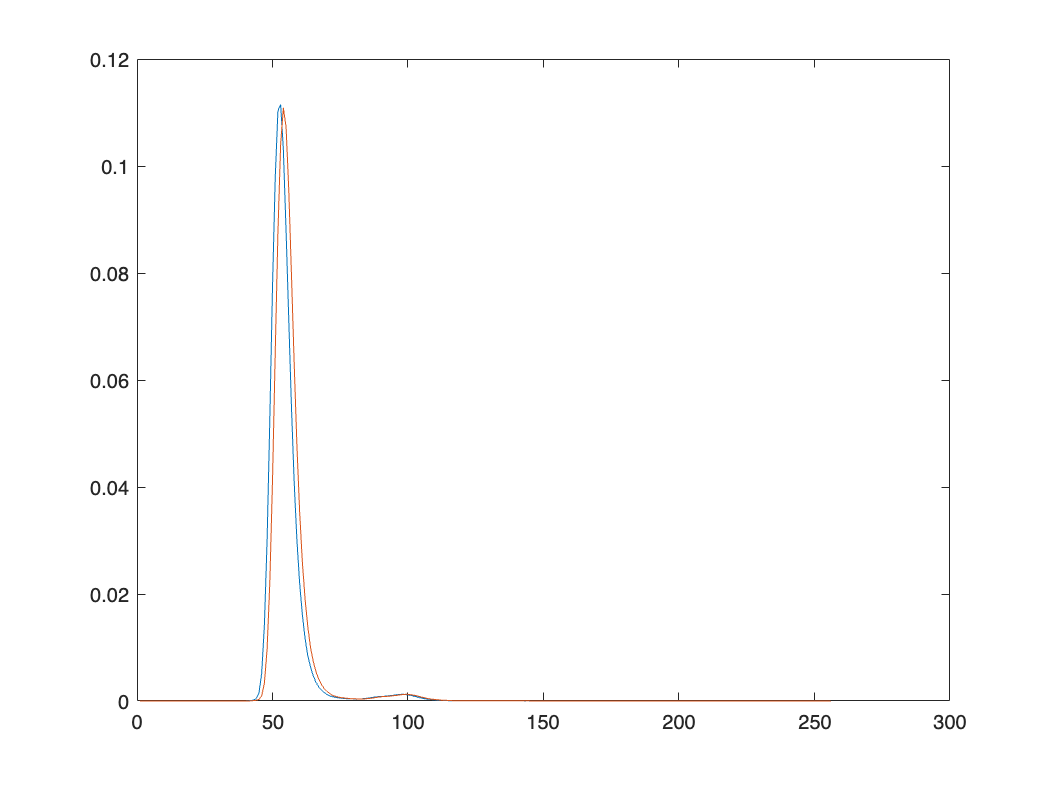


figure
plot(prf)
hold on
plot(prf_interp1)

% save this prf for future use
prf=prf_interp1;
prf_interp1_name='prf_ACh_interp1.mat';
save(prf_interp1_name,'prf')

% select a ROI or two, fix the offset at 0 for empirical lifetime
% find the corresponding functions to calculate the roi lifetime

global offset fixedoffset
fixedoffset=1;
offset=0;
spc_adjustTauOffset(1)

ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM119.mat'

spc_openCurves(ACh_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM119.mat


icycle = 1;
iCell = 1;
photoncount_ACh_mean = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

photoncount_ACh_mean = 131.1173

lft_ACh=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

lft_ACh = 4.6788

ROIsize_ACh=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell}))

ROIsize_ACh = 938

photoncount_ACh = photoncount_ACh_mean * ROIsize_ACh

photoncount_ACh = 122988

% go to another file of baseline condition
baseline_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM0' num2str(baseline_acq_cycle1) '.mat']

baseline_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM053.mat'

spc_openCurves(baseline_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM053.mat


icycle = 1;
iCell = 1;
photoncount_baseline_mean = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

photoncount_baseline_mean = 36.1192

lft_baseline=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

lft_baseline = 4.5339

ROIsize_baseline=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell}))

ROIsize_baseline = 898

photoncount_baseline = round(photoncount_baseline_mean * ROIsize_baseline)

photoncount_baseline = 32435

% Name the population of double exponential decay
PopulationName='ACh_population_20221222'

PopulationName = 'ACh_population_20221222'

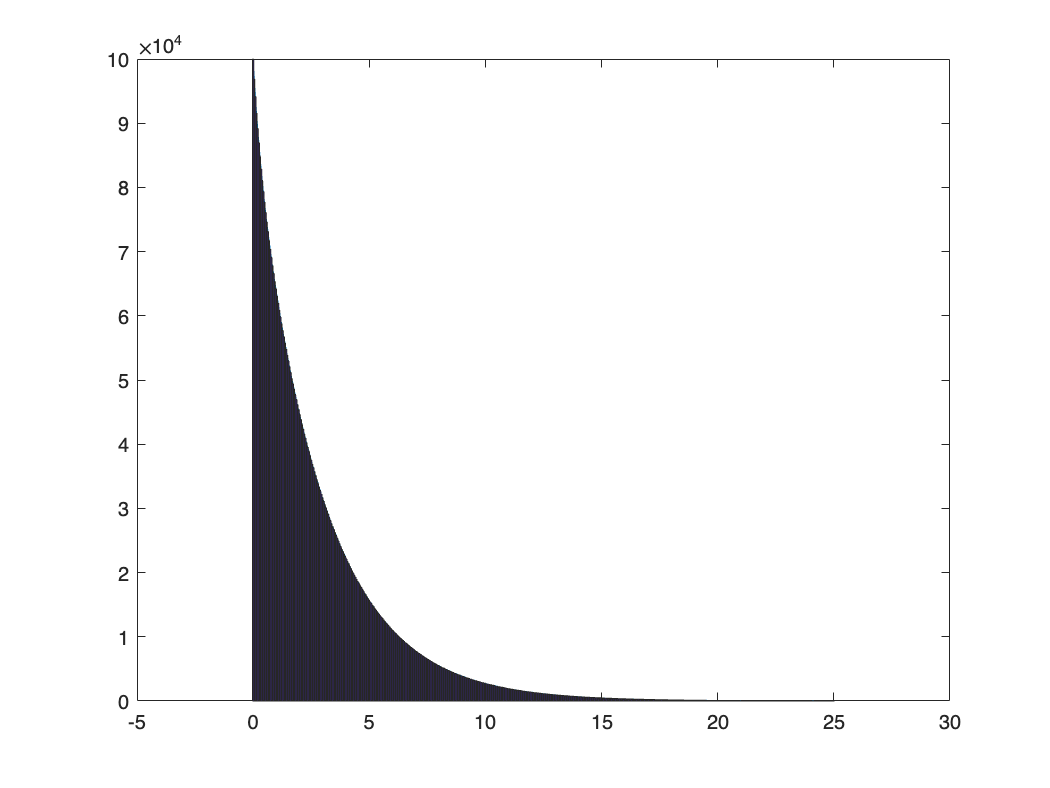

     5367066



% generate the double exponential population, no SHG added, 512 channels
GenPop512_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,PopulationName)

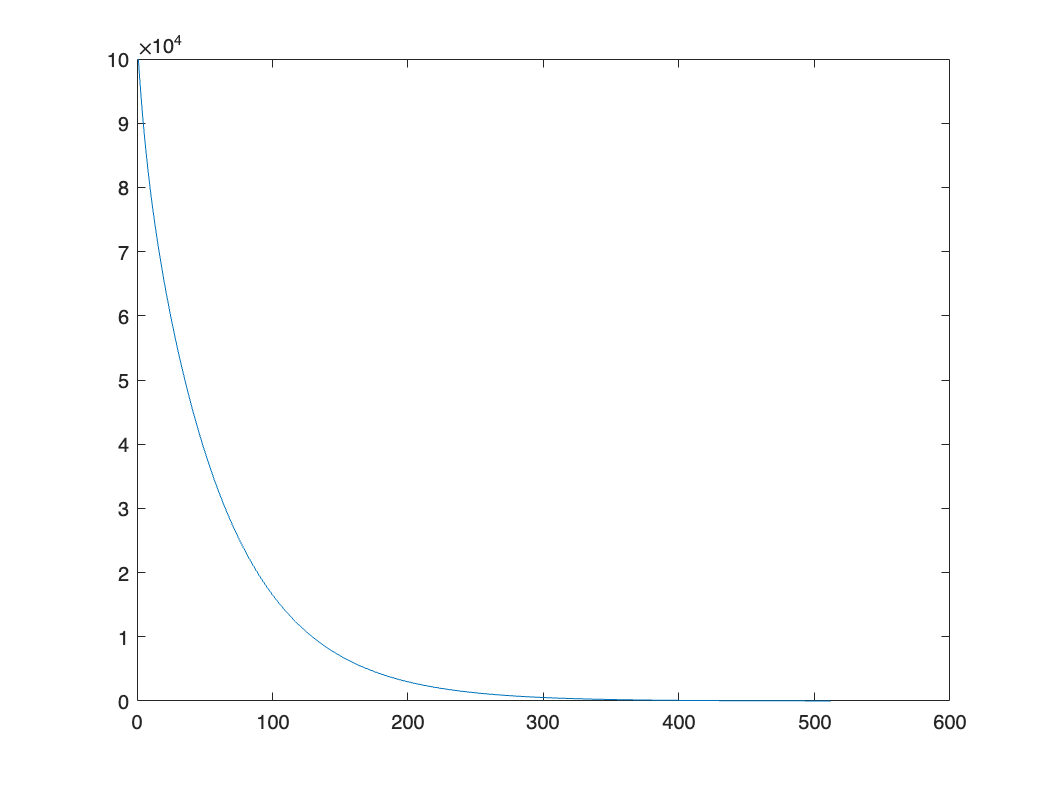

%% Test the population generated is ok. Calculate the analytical lft for each population

load(PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

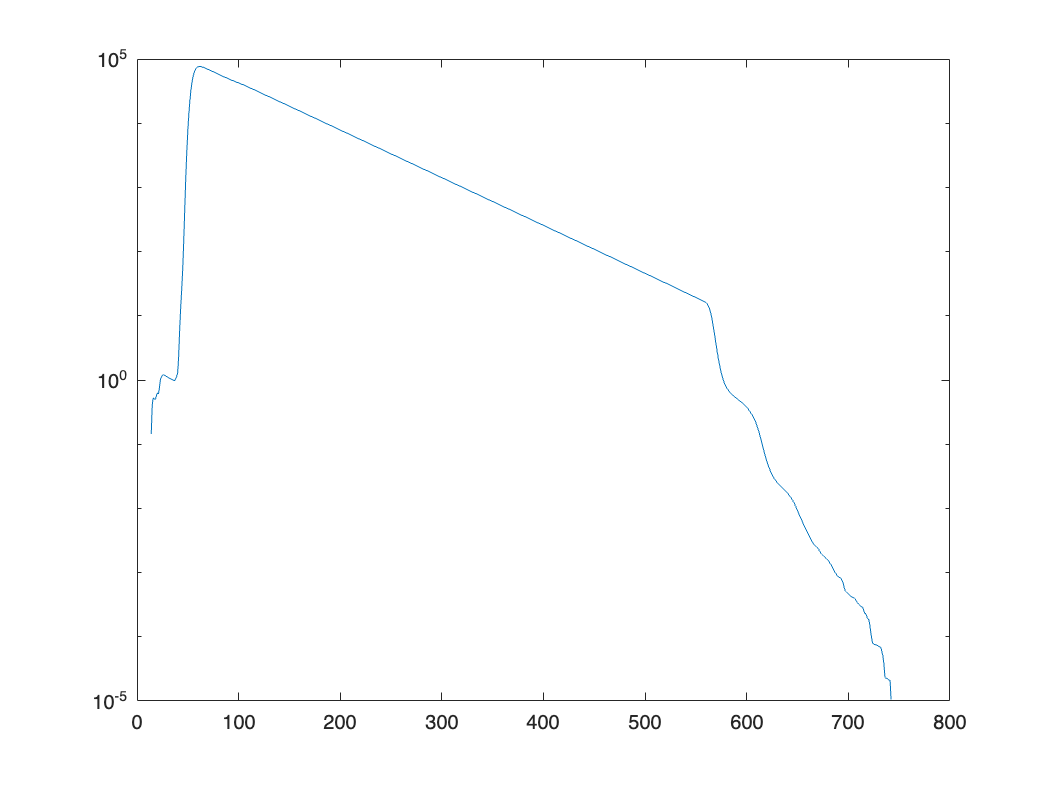


% convolute the double exponential curve use the new prf
conv_n=conv(n,prf);
figure % plot right after the convolution
semilogy(conv_n)

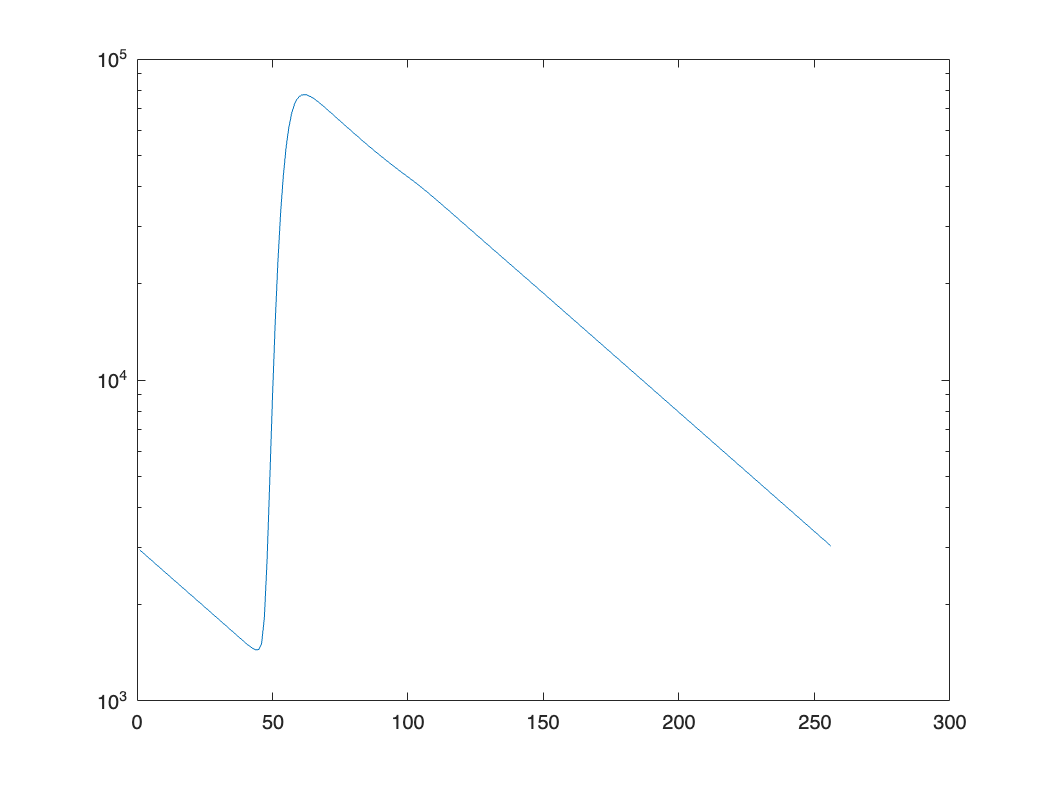


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1; % wrap around

figure
semilogy(conv_n_final) % plot after wrap around


% before background correction, calculate the empirical lifetime

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*conv_n_final(range(1):range(2));
empirical_lft=sum(weight_n_lft)/sum(conv_n_final(range(1):range(2)))

empirical_lft = 4.6352


% add the background correction term, calculate the empirical lifetime
backcorr_ratio=backcorr/samplesize_ACh;
backcorr_ACh=sum(conv_n_final)*backcorr_ratio

backcorr_ACh = 726.4090

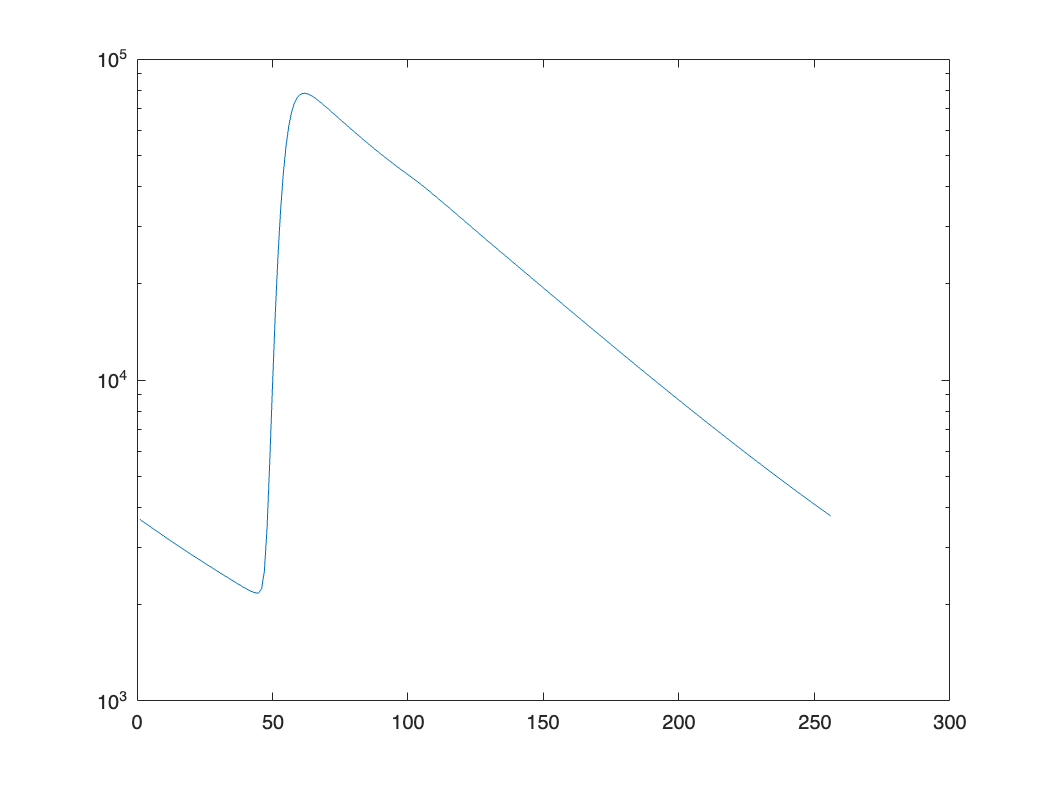

conv_n_final_corr=conv_n_final+backcorr_ACh;
figure
semilogy(conv_n_final_corr)


% from the fitted curve: empirical_lft_ACh_curve = 3.4850
weight_n_lft=lft_steps.*conv_n_final_corr(range(1):range(2));
empirical_lft_PopNoSHG=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

empirical_lft_PopNoSHG = 4.6627



% so generation of the population is good. Then move to simulation

copyfile /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/autofluorescence.mat autofluorescence.mat

load('autofluorescence.mat')

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*AutoFluo0917(range(1):range(2));
empirical_lft_autofluo=sum(weight_n_lft)/sum(AutoFluo0917(range(1):range(2)))

empirical_lft_autofluo = 4.0566

% test the simulation, if no dark count, no afterpulse, no
% autofluorescence, simulate and then add background correction, the
% lifetime should be similiar to the fitted curve
DC=0;
afterpulse=0;
AF=0;
SaveName='test_sim.mat'

SaveName = 'test_sim.mat'

FLIMsim512_Ach(samplesize_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName)

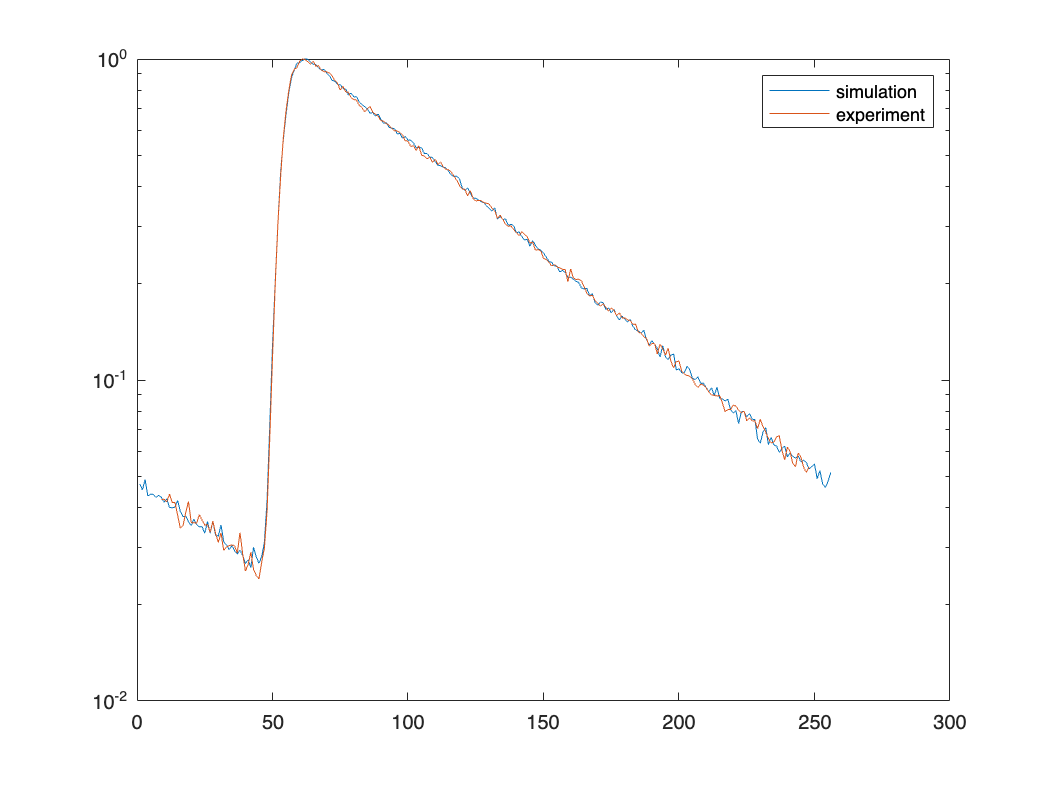

load(SaveName)
figure
% semilogy(n_final)

n_final=n_final+backcorr;
% hold on
semilogy(n_final/(max(n_final)))

hold on
semilogy(n_exp_ACh/max(n_exp_ACh))
legend('simulation','experiment')


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*n_final(range(1):range(2));
empirical_lft_curveonly=sum(weight_n_lft)/sum(n_final(range(1):range(2)))

empirical_lft_curveonly = 4.6646


% from the fitted curve: empirical_lft_ACh_curve = 3.8608
% so the simulation should be good.


% Now do the real simulation, for real simulaition, for autofluorescence should have already include the dark count and SHG term
% So I'll use the population without SHG, and add no dark count to the
% simulated sample.

% first start with no autofluorescence, no after pulse
% use photoncount from the ROI for simulation

DC=0;
AF=0;
afterpulse=0;
mkdir('ACh')
mkdir('baseline')

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 4.6622

mean(simulated_lft_baseline)

ans = 4.6634

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 4.6347

mean(simulated_lft_baseline)

ans = 4.6360

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];
lft_steps=(1:1:256)*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 5.1016

mean(simulated_lft_baseline)

ans = 5.1029

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];
lft_steps=(1:1:256)*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 5.0742

mean(simulated_lft_baseline)

ans = 5.0755

% then add afterpulse as 0.8% of the total
DC=0;
AF=0;
afterpulse=0.008;
mkdir('ACh_afterpulse')
mkdir('baseline_afterpulse')

for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AP=[];
simulated_lft_baseline_AP=[];

for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AP(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr_baseline*(photoncount_baseline/samplesize_baseline);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AP(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh_AP)

ans = 4.6430

mean(simulated_lft_baseline_AP)

ans = 4.6429

% then add autofluorescence, based on the ROIsize
DC=0;
AF=round(20000*ROIsize_ACh/(128*128))

AF = 1145

afterpulse=0.008;
mkdir('ACh_afterpulse_AF')

mkdir('baseline_afterpulse_AF')



for i=1:100
    SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AF=[];
simulated_lft_baseline_AF=[];

for i=1:100
    SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AF(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AF(i)=empirical_lft_baseline;
end


mean(simulated_lft_ACh_AF)

ans = 4.6388

mean(simulated_lft_baseline_AF)

ans = 4.6244

load('autofluorescence.mat')
AF=20000;
n_norm=conv_n_final/sum(conv_n_final)
figure
semilogy(n_norm)

n_ACh=n_norm*photoncount_ACh+AutoFluo0917*AF*ROIsize_ACh/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_ACh)
figure
semilogy(n_ACh)

n_baseline=n_norm*photoncount_baseline+AutoFluo0917*AF*ROIsize_baseline/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_baseline)
figure
semilogy(n_baseline)

% empirical_lft_ACh = 5.1762
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*n_ACh(range(1):range(2));
empiricallft_ACh=sum(weight_n_lft)/sum(n_ACh(range(1):range(2)))

% empirical_lft_baseline = 5.0480
weight_n_lft=lft_steps.*n_baseline(range(1):range(2));
empiricallft_baseline=sum(weight_n_lft)/sum(n_baseline(range(1):range(2)))

save('simulation_20221222.mat')